clc
clear 

**QNC Multiple Comparisons Exercises **

09/22/2023

Mia Sherer

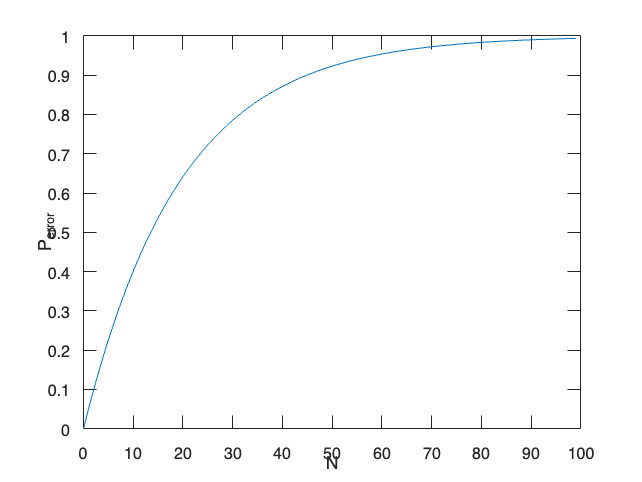

%%Run the cell below to see that the probability of 
% getting a Type I error under these conditions grows 
% rapidly with N, implying that it becomes very, 
% very likely that you will get a 
% "statistically significant result" 
% just by chance if you do enough tests:

alpha = 0.05;
N = 0:99; % Creates an array from 0 to 99
P_error = 1 - (1 - alpha).^N;

plot(N, P_error);
xlabel('N');
ylabel('P_{error}');

%%Bonferroni correction
%The simplest way to correct for Type I errors (false positives) 
% in multiple comparisons is to divide 𝛼  by the number of comparisons, 
% known as the Bonferroni correction. 
% This is a very conservative test 
% that is typically used when the number of comparisons 
% is relatively small and you want to avoid Type I errors.

%%Benjamini–Hochberg procedure
% Another approach is to more carefully control the false-discovery 
% rate using the Benjamini–Hochberg procedure:
% 1. Rank the individual p-values in ascending order, labeled i=1...n

% 2. For each p-value, calculate its "critical value" as (i/n)Q, 
% where i is the rank, n is the total number of tests, and Q is the 
% false discovery rate (a percentage) that you choose (typically 0.05).

% 3. In your rank-ordered, original p-values, find the largest value 
% that is smaller than its associated critical value; this p-value 
% is the new criterion (i.e., reject  𝐻0  for all cases for which p ≤ this value).

%%Exercise 
%First, simulate multiple (say, 1000) t-tests comparing two samples with 
% equal means and standard deviations, and save the p-values. Obviously, 
% at p<0.05 we expect that ~5% of the simulations to yield a "statistically significant" 
% result (of rejecting the NULL hypothesis that the samples come from distributions with equal means).

% Parameters
nSimulations = 1000; % Number of simulations
sampleSize = 100; % Sample size for each group
alpha = 0.05; % Significance level

% Initialize an array to store p-values
p_values = zeros(1, nSimulations);

% Define the true population parameters
true_mean = 0;
true_std = 1;

% Perform t-tests and collect p-values
for i = 1:nSimulations
    % Generate two random samples from the same distribution
    sample1 = true_mean + true_std * randn(1, sampleSize);
    sample2 = true_mean + true_std * randn(1, sampleSize);
    
    % Perform a two-sample t-test
    [~, p_value] = ttest2(sample1, sample2);
    
    % Store the p-value
    p_values(i) = p_value;
end

% Count the number of "statistically significant" results
significant_results = sum(p_values < alpha);

% Display the result
fprintf('Number of statistically significant results: %d out of %d\n', significant_results, nSimulations);

Number of statistically significant results: 34 out of 1000


fprintf('Expected number of significant results at alpha=%.2f: %.2f\n', alpha, nSimulations * alpha);

Expected number of significant results at alpha=0.05: 50.00


%% Second, once you have the simulated p-values, 
% apply both methods to address the multiple comparisons problem.

% Parameters Bonferroni correction 
alpha = 0.05; % Significance level
nSimulations = 1000; % Number of simulations

% Load or generate the simulated p-values (replace with your actual p-values)
% p_values = ...; % Uncomment and replace with your actual p-values

% Number of comparisons
nComparisons = nSimulations;

% Apply Bonferroni Correction
adjusted_alpha_bonferroni = alpha / nComparisons;

% Count the number of p-values that are statistically significant after Bonferroni Correction
significant_indices_bonferroni = find(p_values < adjusted_alpha_bonferroni);
num_significant_bonferroni = length(significant_indices_bonferroni);

% Display the results
fprintf('Bonferroni Correction:\n');

Bonferroni Correction:


fprintf('Number of significant results after correction: %d\n', num_significant_bonferroni);

Number of significant results after correction: 0


fprintf('Adjusted alpha (Bonferroni): %.6f\n', adjusted_alpha_bonferroni);

Adjusted alpha (Bonferroni): 0.000050


% Parameters BH procedure 
alpha = 0.05; % Significance level
nSimulations = 1000; % Number of simulations
Q = 0.05; % False discovery rate (FDR)

% Load or generate the simulated p-values (replace with your actual p-values)
% p_values = ...; % Uncomment and replace with your actual p-values

% Sort the p-values in ascending order
sorted_p_values = sort(p_values);

% Number of comparisons
nComparisons = nSimulations;

% Calculate the critical values
critical_values = (1:nComparisons) * Q / nComparisons;

% Find the largest p-value that is smaller than its associated critical value
significant_indices_bh = find(sorted_p_values <= critical_values);

% Determine the new criterion for significance
if ~isempty(significant_indices_bh)
    threshold_p_value = sorted_p_values(max(significant_indices_bh));
else
    threshold_p_value = 0; % No significant results
end

% Identify the significant results based on the threshold p-value
significant_indices_bh = find(p_values <= threshold_p_value);
num_significant_bh = length(significant_indices_bh);

% Display the results
fprintf('Benjamini-Hochberg Procedure:\n');

Benjamini-Hochberg Procedure:


fprintf('Number of significant results after correction: %d\n', num_significant_bh);

Number of significant results after correction: 0


fprintf('Selected Q (False Discovery Rate): %.4f\n', Q);

Selected Q (False Discovery Rate): 0.0500


%Third, set the sample 1 and sample 2 means to be 1 and 2 respectively, 
% and re-run the exercise. 
% 
% What do you notice? 
% When the means are relatively close (1 and 2), 
% you may still observe statistically significant results, 
% but not as frequently as when the means are equal. 
% The Bonferroni correction and Benjamini-Hochberg procedure 
% still control the family-wise error rate and false discovery rate, respectively, 
% but the number of significant results should be less than when the means are equal.

% What if you make the difference between means even greater?
%If you increase the difference between 
% the means you will likely observe more statistically significant results. 
% As the difference between the means becomes larger, it becomes easier 
% to detect a significant difference, and more p-values will fall below the 
% significance threshold.

